ECE 537 

Exercise #3

Group 5

Muqian Gui ----- V00870654

Hang Ruan ----- V00923058

clc;
clear all;
close all;

load("exercise1Data.mat");
% plot3(exercise1Data(:,1), exercise1Data(:,2), exercise1Data(:,3),'.');

x = exercise1Data';
label = [ones(1,1000) 2*ones(1,1000) 3*ones(1,1000)];
vec = label'; 
y = (vec==1:3)';

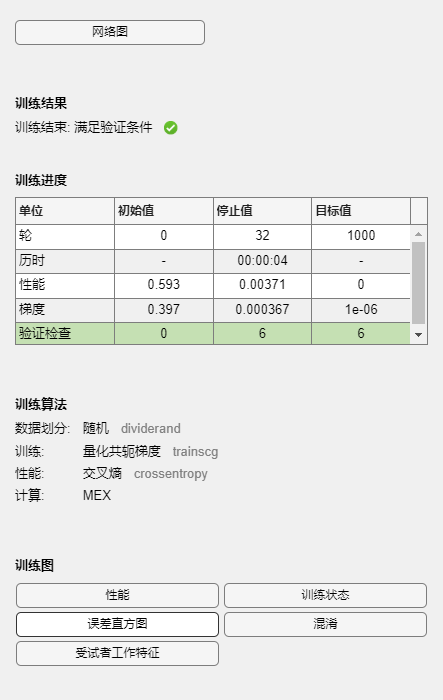

% Decision boundaries plotted by the trained neural network classifier
rng(100);
% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 29-May-2023 16:26:43
%
% This script assumes these variables are defined:
%
%   x - input data.
%   y - target data.
x = x;
t = y;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);


% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0045

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.0043

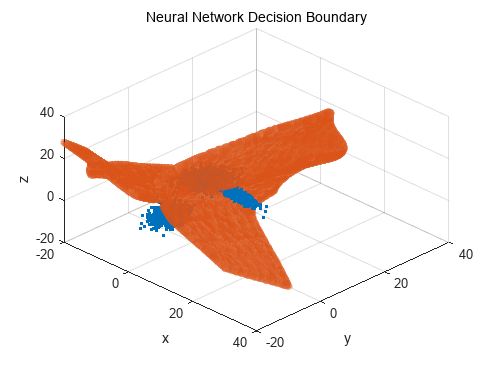


% View the Network
% view(net);

% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
%figure, plotconfusion(t,y)
%figure, plotroc(t,y)

vol = vol3D([-20 30 -20 30 -20 30], 200);
volt = vol';
outputs = net(volt);

% [m,n] = size(outputs)
% outputs(5,2)
[decBoun_inds1 decBoun_inds2 decBoun_inds3  decBoun_inds4 ]= decision_boundary_inds(outputs);
d_inds = [decBoun_inds1 decBoun_inds2 decBoun_inds3 decBoun_inds4 ];
[X Y Z] = decision_boundary_points(volt,d_inds);
decBounNN = [X; Y; Z];

figure
plot3(exercise1Data(:,1), exercise1Data(:,2), exercise1Data(:,3),'.');
hold on
scatter3(decBounNN(1,:)',decBounNN(2,:)',decBounNN(3,:)','filled','MarkerFaceAlpha',0.25)
hold off
view(45,45)
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Neural Network Decision Boundary')

Based on the results obtained from the trained neural network. I would like to conclude that the result decision boundaries plotted here can be regarded as correct one. To determine the correctness of the boundaries from neural network should be based on the performance in classification tasks. As this one showed the percetError is only 0.0043. Which can be seen as a very success classifier. The Bayesian decision boundaries are more considering the prior probabilities and the likelihoood of the data given each class. It is hard to conclude in general which one is more correct. Neural network might be able dealing with complex patterns better. If only consider the results from this dataset. I would like to indicate that the decision boundaries generated by the trained neural network is more correct than Bayesian one.

Matlab’s computation of the trained neural network’s error is valid given an correct implementation of an accurate loss function, efficient training, validation, and testing splitting. Our neural network uses a balanced data split, evaluated the error properly and showed a decrease in error as the number of iterations increases. Matlab’s computation of the trained neural network’s error is correct.

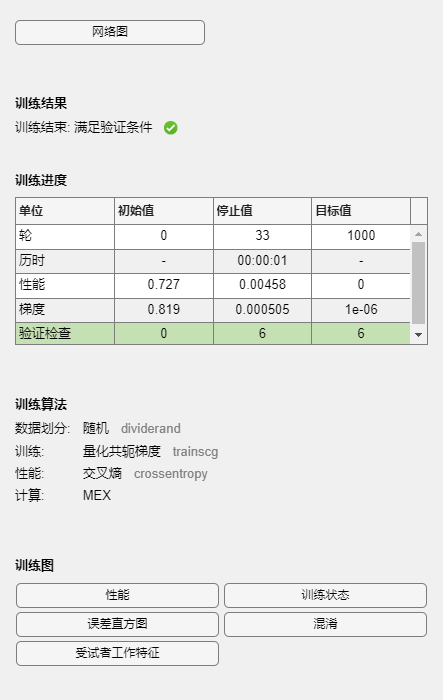

% Decision boundaries plotted by the trained neural network classifier with
% more neurons
rng(100);
% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 29-May-2023 16:26:43
%
% This script assumes these variables are defined:
%
%   x - input data.
%   y - target data.
x = x;
t = y;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 30;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);


% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0050

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 3.3333e-04

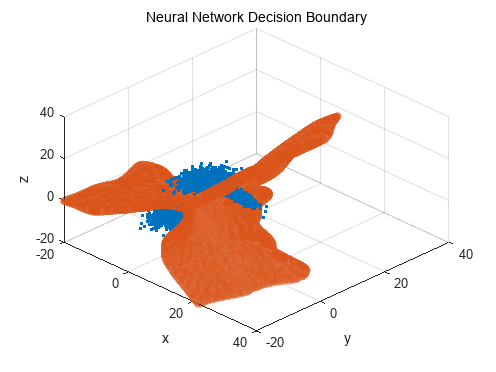


% View the Network
% view(net);

% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
%figure, plotconfusion(t,y)
%figure, plotroc(t,y)

vol = vol3D([-20 30 -20 30 -20 30], 200);
volt = vol';
outputs = net(volt);

% [m,n] = size(outputs)
% outputs(5,2)
[decBoun_inds1 decBoun_inds2 decBoun_inds3  decBoun_inds4 ]= decision_boundary_inds(outputs);
d_inds = [decBoun_inds1 decBoun_inds2 decBoun_inds3 decBoun_inds4 ];
[X Y Z] = decision_boundary_points(volt,d_inds);
decBounNN = [X; Y; Z];

figure
plot3(exercise1Data(:,1), exercise1Data(:,2), exercise1Data(:,3),'.');
hold on
scatter3(decBounNN(1,:)',decBounNN(2,:)',decBounNN(3,:)','filled','MarkerFaceAlpha',0.25)
hold off
view(45,45)
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Neural Network Decision Boundary')

This plot presented the decision boundaries generated by a trained neural network with 30 neurons. it is not difficult to see that this decision boundaries classfied each class more clearly. And the percentError is also lower than before.  As more neurons add to the hidden layer, it increases the neural network's capacity to deal with complex decision boundaries.To catch finer details and handle more complex data features. The risk for more neurons will be the issue of overfitting. In this dataset, increase the number of neurons to 30 helps to obtained a more correct decision boundary. But still the risk of overfitting should be considered.

performance = 0.0048

percentErrors = 0

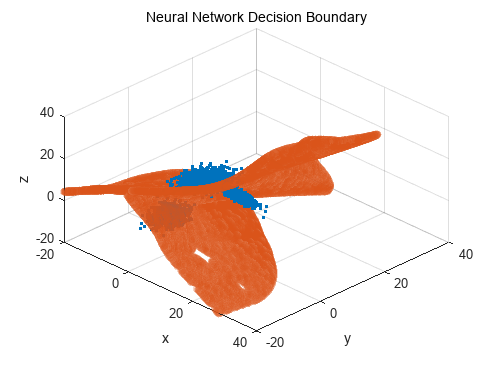

performance = 0.0049

percentErrors = 3.3333e-04

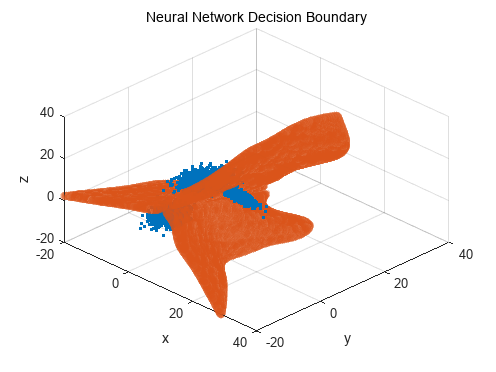

performance = 0.0059

percentErrors = 3.3333e-04

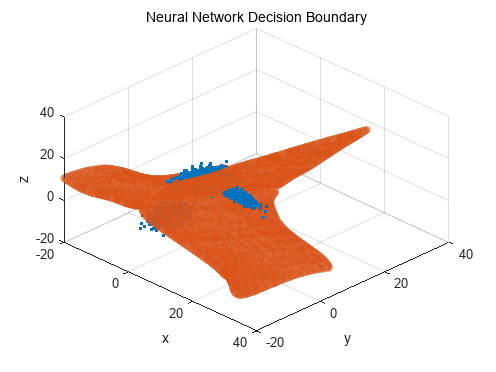

performance = 0.0055

percentErrors = 0

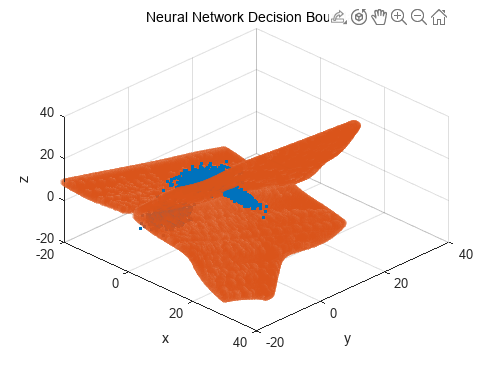

performance = 0.0055

percentErrors = 0

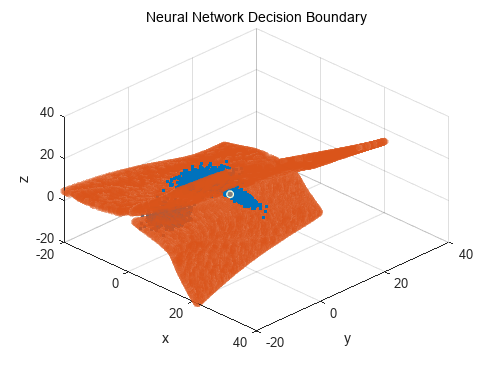

performance = 0.0057

percentErrors = 0

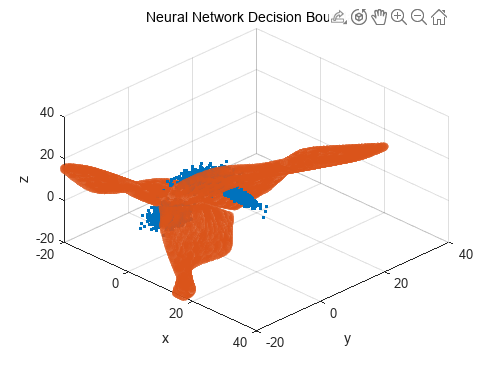

performance = 0.0053

percentErrors = 0

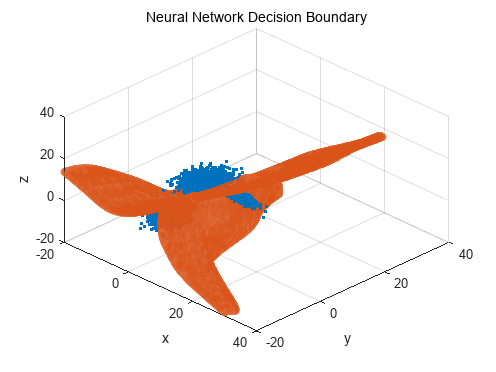

performance = 0.0056

percentErrors = 6.6667e-04

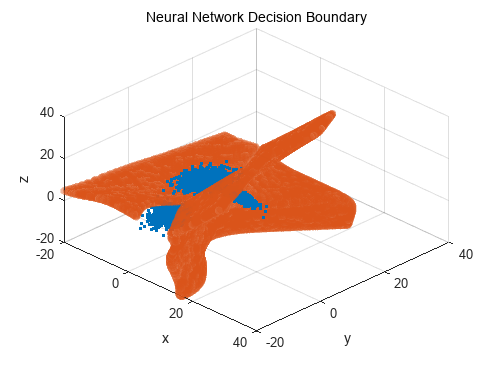

performance = 0.0059

percentErrors = 0

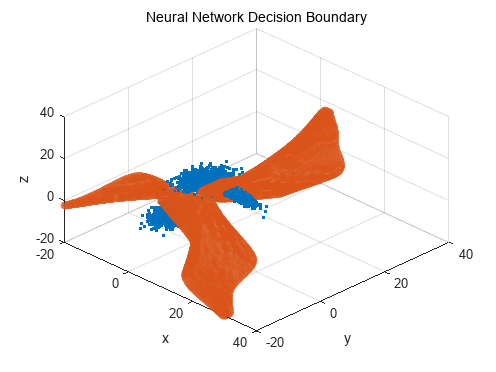

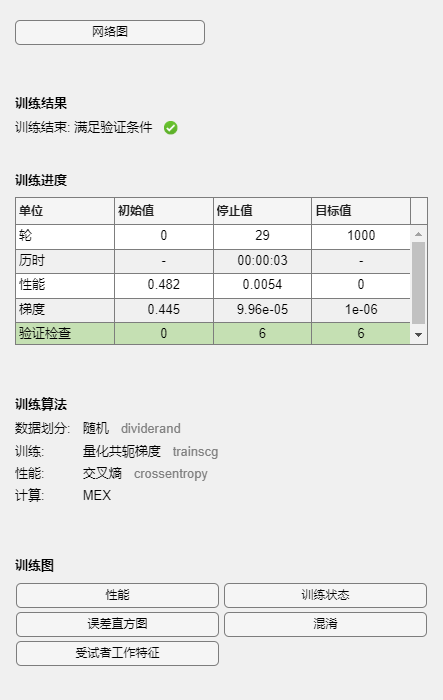

performance = 0.0058

percentErrors = 3.3333e-04

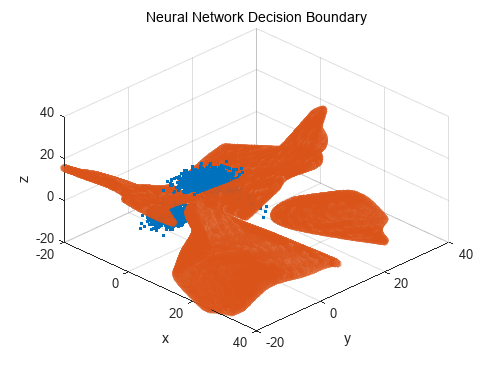

% Train the network with 10 different random seed

numTrainings = 10;
for i = 1:numTrainings
    % Set random seed
    seed = i;  % Use a different seed for each training iteration
    rng(seed);

x = x;
t = y;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)
tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

% View the Network
% view(net);

vol = vol3D([-20 30 -20 30 -20 30], 200);
volt = vol';
outputs = net(volt);


[decBoun_inds1 decBoun_inds2 decBoun_inds3  decBoun_inds4 ]= decision_boundary_inds(outputs);
d_inds = [decBoun_inds1 decBoun_inds2 decBoun_inds3 decBoun_inds4 ];
[X Y Z] = decision_boundary_points(volt,d_inds);
decBounNN = [X; Y; Z];

figure
plot3(exercise1Data(:,1), exercise1Data(:,2), exercise1Data(:,3),'.');
hold on
scatter3(decBounNN(1,:)',decBounNN(2,:)',decBounNN(3,:)','filled','MarkerFaceAlpha',0.25)
hold off
view(45,45)
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Neural Network Decision Boundary')


end

Based on the results obtained with different randomo seed setup. The decision boundaries obtained each time are different from each otehrs. Because for different random seed. The initial weights and biases will be different. This will generate different learned parameters for the neural network. THerefor, the decision boundaries will be different. One thing might happened with 100 different neural network might give 100 different decision boundaries. But if this 100 different neural network are worked together, this might reault a more robust decision boundariy. In conclusion, the different decision boundaries generated is due to different weights and bias for each neural network which will give different learned parameter can result different performance of each neural network.

Decision boundaries from trained neural network can be seen as a correct one must show it's strong ability to classified data correctly adn without overfitting problem.  With considering the evaluation matrix, quality of data and some specific consideration for different problems. In this problem, we can use the percentError to determine if the decision boundary is correct. The low percentError means less misclassification which will result a more correct decision boundary.

Neural networks will not be able to produce decision boundaries equivalent to the Bayes boundaries. Neural networks can estimate non-linear relationships using various activation functions. But it doesn’t provide posterior probability or incorporate prior information and probability distribution. And in the scenario where the dataset gets too big, the model is prone to overfitting. Similarly, if the training data is not well prepared and not able to represent the underlying distribution of the problem, the network will not able to produce decision boundaries close to Bayes boundaries. In addition, Bayes boundaries is derived on some assumptions which will not be considered when neural network learn the dataset. Thus, neural network will not be able to produce decision boundaries equivalent to the Bayes boundaries. 

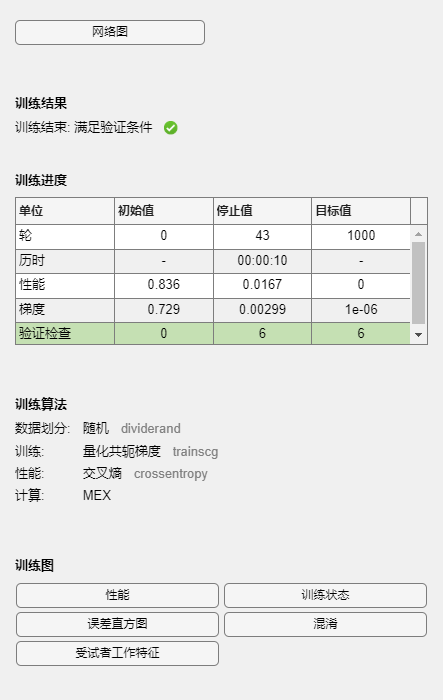

% Decision boundaries plotted by the trained neural network classifier with
% outlier data
load("datawithoutlier.mat"); 
% plot3(exercise1Data(:,1), exercise1Data(:,2), exercise1Data(:,3),'.');

x_o = data_with_outlier';
label = [ones(1,1003) 2*ones(1,1000) 3*ones(1,1000)];
vec = label'; 
y_o = (vec==1:3)';

rng(100);
% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 29-May-2023 16:26:43
%
% This script assumes these variables are defined:
%
%   x - input data.
%   y - target data.
 
x = x_o;
t = y_o;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);


% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0170

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.0143

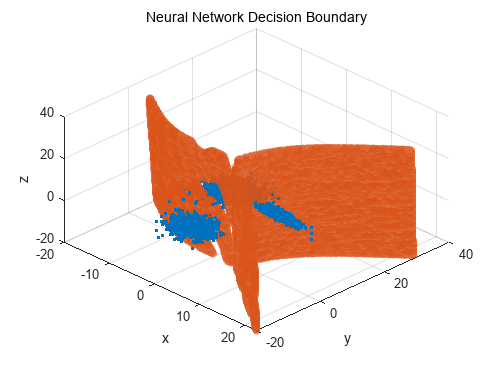


% View the Network
% view(net);

% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
%figure, plotconfusion(t,y)
%figure, plotroc(t,y)

vol = vol3D([-20 30 -20 30 -20 30], 200);
volt = vol';
outputs = net(volt);

% [m,n] = size(outputs)
% outputs(5,2)
[decBoun_inds1 decBoun_inds2 decBoun_inds3  decBoun_inds4 ]= decision_boundary_inds(outputs);
d_inds = [decBoun_inds1 decBoun_inds2 decBoun_inds3 decBoun_inds4 ];
[X Y Z] = decision_boundary_points(volt,d_inds);
decBounNN = [X; Y; Z];

figure
% plot3(data_with_outlier(:,1), data_with_outlier(:,2), data_with_outlier(:,3),'.');
plot3(exercise1Data(:,1), exercise1Data(:,2), exercise1Data(:,3),'.');
hold on
scatter3(decBounNN(1,:)',decBounNN(2,:)',decBounNN(3,:)','filled','MarkerFaceAlpha',0.25)
hold off
view(45,45)
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Neural Network Decision Boundary')

As the results obtained here, the decision boundaries still indeicated some influences from the outlier data. No matter from the shap of the decision boundaries or the percentError, the performance is getting worse than before. But compare with the performance of Bayesian decision boundary, it still doing better. The increasing percentError indicate that some misclassification will occur with outlier data. But mostly, it still can do the classification correct. From my view, the neural network boundaries will less sensitive to outliers than the Bayesian boundaries.

When allowing the model to train on a larger dataset(90% training, 10% testing), it typically learns from more examples in order to capture the patterns in the set. However, it also makes it more prone to overfitting that the model is memorizing the training data instead of the pattern within it. The dataset split going from 90:10 to 10:90 can lower the performance of the model given it has fewer examples to learn from. However, it improves the model’s generalizability by evaluating the model on more unseen examples and it also lowers the risk of overfitting. Therefore, it’s essential to find the right balance between training and testing data to achieve good performance.

function [AB AC BC ABC] = decision_boundary_inds(out)

AB = [];
AC = [];
BC = [];
ABC = [];
[m,n] = size(out);


for i = 1:n
    p1 = out(1,i); 
    p2 = out(2,i);
    p3 = out(3,i);


    if (  abs(p1 - p2)<0.06 & p3 < 0.1 )
    
        AB = [AB i];
    else
        AB = AB;
       
    end

    if (  abs(p1 - p3)<0.06 & p2 < 0.1 )
    
        AC = [AC i];
    else
        AC = AC;
       
    end
    if (  abs(p3 - p2)<0.06 & p1< 0.1 )
    
        BC = [BC i];
    else
        BC = BC;
       
    end

%     if (  abs(p3 + p2-2*p1)<0.03 | abs(p1 + p2-2*p3)<0.03 | abs(p3 + p1-2*p2)<0.03 )
%     
%         ABC = [ABC i];
%     else
%         ABC = ABC;
%        
%     end

    AB;
    AC;
    BC;
    ABC;

end
end

function [X Y Z ] = decision_boundary_points(grid_point,inds)
x1 = grid_point(1,:);
y1 = grid_point(2,:);
z1 = grid_point(3,:);
X = [];
Y = [];
Z = [];

[c,s] = size (inds);

for i = 1:s
    num = inds(1,i);
    x_add = x1(1,num);
    y_add = y1(1,num);
    z_add = z1(1,num);
    X = [X, x_add ];
    Y = [Y, y_add ];
    Z = [Z, z_add ];
end

X;
Y;
Z;

end